clc; clear all;
rng(43);
robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Loading **KukaIiwa7** Robot

numJoints = numel(homeConfiguration(robot));
endEffector = 'iiwa_link_ee_kuka';
helperCreateObstaclesKINOVA;

taskInit = trvec2tform([[0.5 0.2 -0.2]])*axang2tform([0 1 0 pi]);
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = findCollisionFreeIK(robot, world, endEffector, taskInit);

taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];

finalRobotJConfig   = findCollisionFreeIK(robot, world, endEffector, taskFinal);

assert(~checkCollision(robot,currentRobotJConfig,world,"IgnoreSelfCollision","on"))
assert(~checkCollision(robot,finalRobotJConfig,   world,"IgnoreSelfCollision","on"))

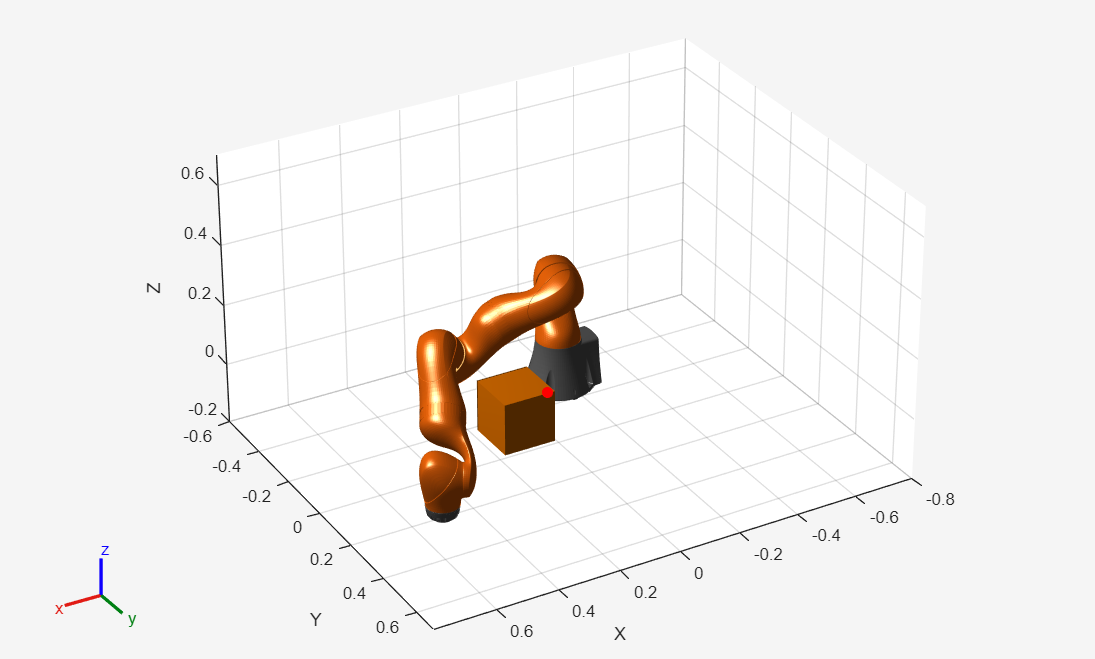

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

safetyDistance = 0.01; 

Elapsed time is 1.748647 seconds.


Qtheta = 232.4508

RAR = 56.0691

Previous Qθ = 256.010243 | New Qθ = 232.450762 | ΔQ = 23.559481
Elapsed time is 1.603958 seconds.


Qtheta = 209.5046

RAR = 56.0701

Previous Qθ = 232.450762 | New Qθ = 209.504563 | ΔQ = 22.946199
Elapsed time is 1.760741 seconds.


Qtheta = 180.0201

RAR = 56.0706

Previous Qθ = 209.504563 | New Qθ = 180.020078 | ΔQ = 29.484485
Elapsed time is 1.636063 seconds.


Qtheta = 150.0020

RAR = 56.0763

Previous Qθ = 180.020078 | New Qθ = 150.002026 | ΔQ = 30.018052
Elapsed time is 1.800034 seconds.


Qtheta = 132.3719

RAR = 56.0720

Previous Qθ = 150.002026 | New Qθ = 132.371896 | ΔQ = 17.630130
Elapsed time is 1.685373 seconds.


Qtheta = 119.1080

RAR = 56.0771

Previous Qθ = 132.371896 | New Qθ = 119.107958 | ΔQ = 13.263938
Elapsed time is 1.589217 seconds.


Qtheta = 105.7338

RAR = 56.0724

Previous Qθ = 119.107958 | New Qθ = 105.733789 | ΔQ = 13.374169
Elapsed time is 1.617505 seconds.


Qtheta = 96.7289

RAR = 56.0794

Previous Qθ = 105.733789 | New Qθ = 96.728857 | ΔQ = 9.004932
Elapsed time is 1.591204 seconds.


Qtheta = 92.9846

RAR = 56.0796

Previous Qθ = 96.728857 | New Qθ = 92.984603 | ΔQ = 3.744255
Elapsed time is 1.604267 seconds.


Qtheta = 86.3866

RAR = 56.0775

Previous Qθ = 92.984603 | New Qθ = 86.386598 | ΔQ = 6.598004
Elapsed time is 1.607703 seconds.


Qtheta = 79.3910

RAR = 56.0793

Previous Qθ = 86.386598 | New Qθ = 79.391007 | ΔQ = 6.995591
Elapsed time is 1.638923 seconds.


Qtheta = 73.2376

RAR = 56.0818

Previous Qθ = 79.391007 | New Qθ = 73.237637 | ΔQ = 6.153370
Elapsed time is 1.601548 seconds.


Qtheta = 79.8097

RAR = 56.0844

Previous Qθ = 73.237637 | New Qθ = 79.809655 | ΔQ = 6.572018
Elapsed time is 1.696231 seconds.


Qtheta = 70.6799

RAR = 56.0830

Previous Qθ = 79.809655 | New Qθ = 70.679886 | ΔQ = 9.129769
Elapsed time is 1.595509 seconds.


Qtheta = 68.5504

RAR = 56.0839

Previous Qθ = 70.679886 | New Qθ = 68.550380 | ΔQ = 2.129506
Elapsed time is 1.621421 seconds.


Qtheta = 67.2266

RAR = 56.0845

Previous Qθ = 68.550380 | New Qθ = 67.226578 | ΔQ = 1.323801
Elapsed time is 1.610743 seconds.


Qtheta = 66.7559

RAR = 56.0867

Previous Qθ = 67.226578 | New Qθ = 66.755895 | ΔQ = 0.470684
Elapsed time is 1.721678 seconds.


Qtheta = 63.5243

RAR = 56.0855

Previous Qθ = 66.755895 | New Qθ = 63.524276 | ΔQ = 3.231618
Elapsed time is 1.708115 seconds.


Qtheta = 62.2868

RAR = 56.0853

Previous Qθ = 63.524276 | New Qθ = 62.286779 | ΔQ = 1.237497
Elapsed time is 1.645902 seconds.


Qtheta = 61.3396

RAR = 56.0878

Previous Qθ = 62.286779 | New Qθ = 61.339574 | ΔQ = 0.947205
Elapsed time is 1.702015 seconds.


Qtheta = 62.0116

RAR = 56.0864

Previous Qθ = 61.339574 | New Qθ = 62.011625 | ΔQ = 0.672051
Elapsed time is 1.631758 seconds.


Qtheta = 60.0549

RAR = 56.0867

Previous Qθ = 62.011625 | New Qθ = 60.054886 | ΔQ = 1.956739
Elapsed time is 1.662648 seconds.


Qtheta = 60.6518

RAR = 56.0892

Previous Qθ = 60.054886 | New Qθ = 60.651818 | ΔQ = 0.596932
Elapsed time is 1.627607 seconds.


Qtheta = 58.6729

RAR = 56.0911

Previous Qθ = 60.651818 | New Qθ = 58.672941 | ΔQ = 1.978877
Elapsed time is 1.635570 seconds.


Qtheta = 60.1435

RAR = 56.0914

Previous Qθ = 58.672941 | New Qθ = 60.143536 | ΔQ = 1.470596
Elapsed time is 1.610892 seconds.


Qtheta = 57.4491

RAR = 56.0900

Previous Qθ = 60.143536 | New Qθ = 57.449094 | ΔQ = 2.694442
Elapsed time is 1.597594 seconds.


Qtheta = 56.5049

RAR = 56.0922

Previous Qθ = 57.449094 | New Qθ = 56.504896 | ΔQ = 0.944198
Elapsed time is 1.610787 seconds.


Qtheta = 56.5089

RAR = 56.0943

Previous Qθ = 56.504896 | New Qθ = 56.508909 | ΔQ = 0.004012
STOMP Finished.


isTrajectoryInCollision = logical
   0


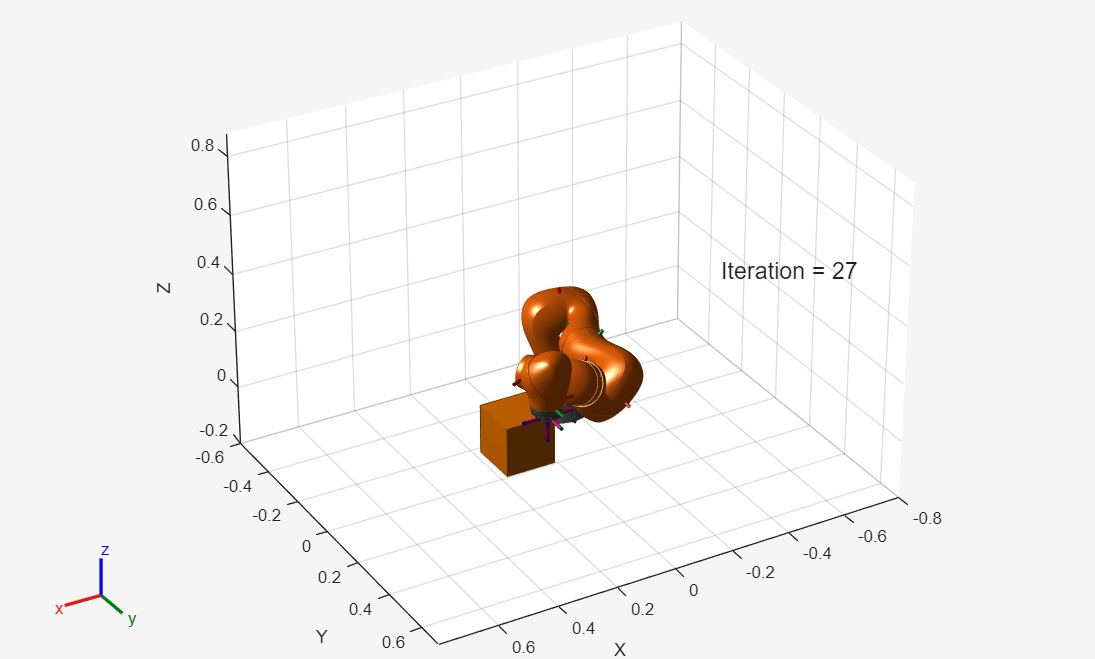

enableVideoTraining = 1;
enableVideo = 1;
helperSTOMP;